# CS283 Assignment 7

Enmao Diao, 2017/10/29

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1

By conservation fo energy,


$$\forall \hat{\mathbf{v}_i}, \quad 0 \leq  \int_{V_{o}}f_r(\hat{\mathbf{v}_i},\hat{\mathbf{v}_o})\cos\theta_o d\hat{\mathbf{v}_o} \leq 1$$


Since BRDF is a constant,


$$=f_r(\hat{\mathbf{v}_i},\hat{\mathbf{v}_o})\int_{V_{o}}\cos\theta_o d\hat{\mathbf{v}_o}$$



$$=f_r(\hat{\mathbf{v}_i},\hat{\mathbf{v}_o})\int_0^{2\pi}\int_0^{\frac{\pi}{2}}\cos\theta_o\sin\theta_o d\theta_od\phi_o$$



$$=f_r(\hat{\mathbf{v}_i},\hat{\mathbf{v}_o})\pi$$



$$=\rho$$


Thus,


$$0\leq \rho\leq1$$
 

# Question 2

.(a)

We extract the $N\times w\times 3$ matrix from bunny.mat and use quiver to show the *x*-*y *components of the normal field.

Resolution is adjusted by plotting only every *n*th element

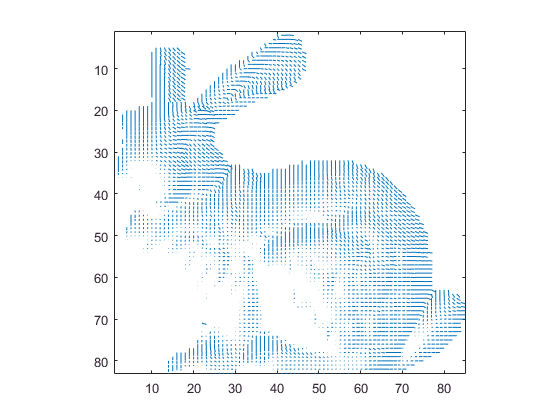

% Question 2(a)
N = load('./data/bunny.mat');
N = N.N;
x = N(:,:,1);
y = N(:,:,2);
n = 5;
s = [0,0,1];
figure; % create a new figure
quiver(x(1:n:end,1:n:end),y(1:n:end,1:n:end),'.');
axis image; % set unit aspect ratio between x and y axes
axis ij; % place origin in top-left corner (like an image)

(b) 


$$L_o(\hat\mathbf{v}) = \int_{V_o}f_{r}(\hat{\mathbf{v}_i},\hat{\mathbf{v}_o})L_{i}(\hat\mathbf{v})\cos\theta_{i}dv_i$$


Assuming Lambertian reflectance and constant albedo $\rho = 1$


$$f_{r}(\hat{\mathbf{v}_i},\hat{\mathbf{v}_o}) = \frac{1}{\pi}$$


Asumming 

 $L_{i}(\hat\mathbf{v})$ is a costant for all $\hat\mathbf{v}_i$, emitting a constant radiance in each direction


$$L_o(\hat\mathbf{v}) =a\int_{V_o}\cos\theta_{i}dv_i $$



$$\cos\theta_i = \frac{\mathbf{n}\cdot \hat\mathbf{s}}{|\mathbf{n}|| \hat\mathbf{s}|}$$


Thus for unit vector $\mathbf{n}$ and $ \hat\mathbf{s}$ ,


$$L_o(\hat\mathbf{v}) =a(\mathbf{n}^T \hat\mathbf{s})$$
 

For $ \hat\mathbf{s} = (0,0,1)$, and $N$is $h\times w\times 3$ (all unit vectors), thus $(x_i,y_i,z_i)\pmatrix{0\cr0\cr1} = z_i$. The result is simply $N(:,:,3)$

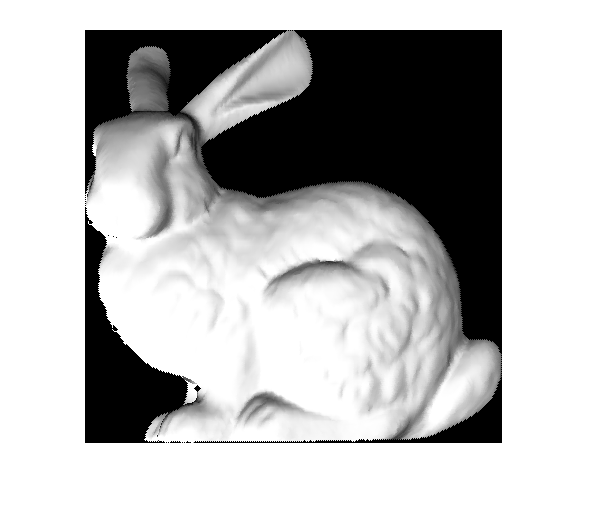

% Question 2(b)
figure
imshow(N(:,:,3))

(c)

Up means positive y-axis, and right means positive x-axis.

Up 45 degrees for $\hat\mathbf{s} = [0,0,1]$ rotates 45 degress along y-axis. We maintain it as a unit vector and the result is [0,cosd(45),cosd(45)]

Right 45 degrees for $\hat\mathbf{s} = [0,0,1]$ rotates 45 degress along x-axis. We maintain it as a unit vector andthe result is [cosd(45),0,cosd(45)]

Right 75 degrees for $\hat\mathbf{s} = [0,0,1]$ rotates 75 degress along x-axis. We maintain it as a unit vector and the result is [cosd(25),0,cosd(75)]

There are some missing points and unreasonable brightness near the boundary of the bunny.

We assume that the light source emits a constant radiance in each direction and we also ignore interreflection illumination effect in our computation.

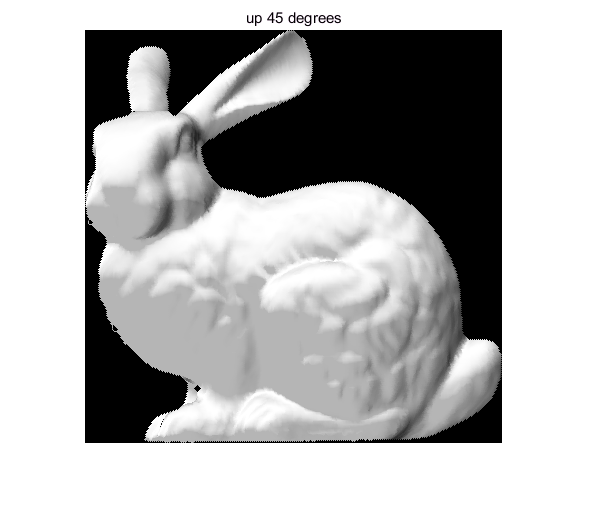

% Question 2(c)
[p,q,z] = size(N);
up45 = [0,cosd(45),cosd(45)];
up45_im = zeros(p,q);
for i = 1:p
    for j = 1:q
        up45_im(i,j) = max([0,squeeze(N(i,j,:))'*up45']);
    end
end
figure
imshow(up45_im)
title('up 45 degrees')

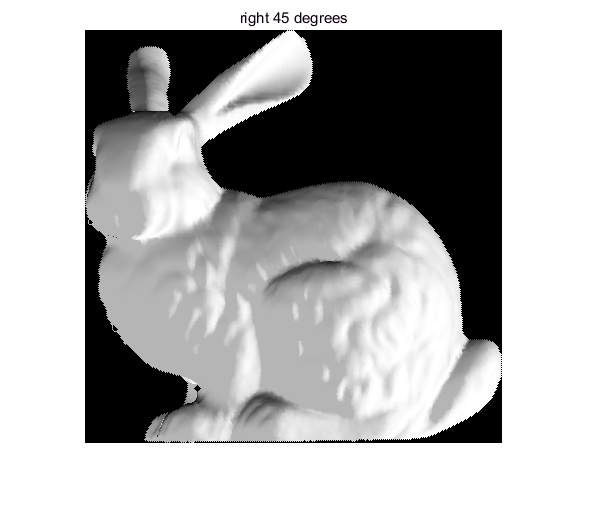


right45 = [cosd(45),0,cosd(45)];
right45_im = zeros(p,q);
for i = 1:p
    for j = 1:q
        right45_im(i,j) =  max([0,squeeze(N(i,j,:))'*right45']);
    end
end
figure
imshow(right45_im)
title('right 45 degrees')

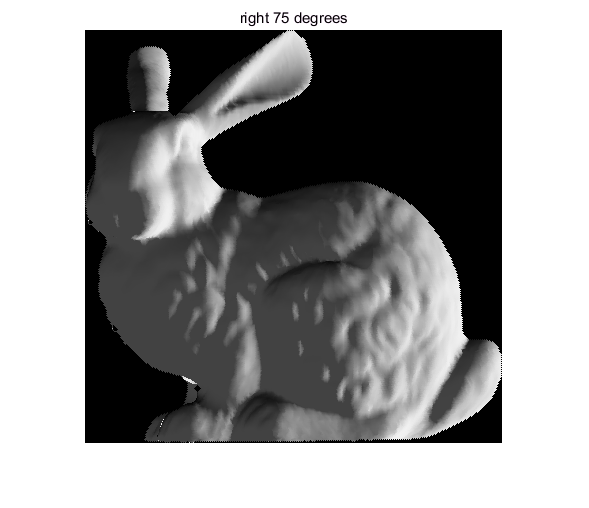


right75 = [cosd(25),0,cosd(75)];
right75_im = zeros(p,q);
for i = 1:p
    for j = 1:q
        right75_im(i,j) =  max([0,squeeze(N(i,j,:))'*right75']);
    end
end
figure
imshow(right75_im)
title('right 75 degrees')

# Question 3

(a)

the solid angle subtended by $dA$ at points $X_1$ is $dw_1$


$$d\omega_1 = \frac{dA\cos\theta}{r^2}
$$


no angle between $P$ and $X_1$, and $r = D$


$$= \frac{dA}{D^2}$$
  

angle is $\alpha$, and $r = \frac{D}{\alpha}$


$$d\omega_2= \frac{dA\cos\alpha}{(\frac{D}{\cos\alpha})^2} =\frac{dA(\cos\alpha)^3}{D^2}$$


(b)

$P$ emits radiance $L$ in each direction.


$$E(X_1) = L(P,\theta,\phi)\cos\theta d\omega_1 = Ld\omega_1 = \frac{(dA)L}{D^2}$$



$$E(X_2) = L(P,\theta,\phi)\cos\theta d\omega_2 = L\cos \alpha d\omega_2 = \frac{dA(\cos\alpha)^4L}{D^2}$$



$$\frac{E(X_1)}{E(X_2)} = \frac{(dA)L}{D^2}/ \frac{dA(\cos\alpha)^4L}{D^2} = \frac{1}{(\cos \alpha)^4}$$


# Question 4

(a) 

Estimate the surface normal and grayscale albedo for each pixel from multiple views

We adopt local shading model


$$B(\mathbf x) = ρ(\mathbf x)N(\mathbf x)\cdot S_1$$


the value of a pixel at (x, y) is  


$$I(x,y) = kB(x,y) = kρ(x,y)N(x,y)\cdot S_1$$



$$= g(x,y)V_1$$


$S_1$ is just the source vector and stored in sources.mat

we can construct $I(x,y)= [I_1(x, y), I_2(x, y), . . ., I_n(x, y)]^T$ for each pixel and for $n=7$ views

Then we can solve the linear system for $g(x,y)$

and the surface normal is $N(x,y) = \frac{g(x,y)}{|g(x,y)|}$, grayscale albedo for each pixel  is $\rho(x,y) = |g(x,y)|$

We use imshow for the albedo values 

We use quiver to show the *x*-*y *components of the normal field.

Resolution is adjusted by plotting only every *n*th element

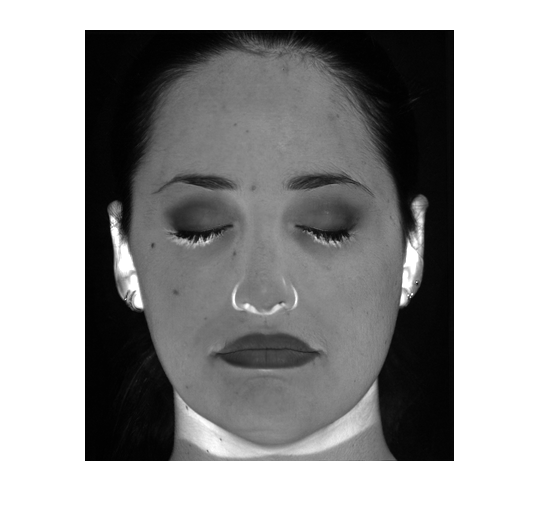

S = load('./data/PhotometricStereo/sources.mat');
V = S.S;
nv = size(V,1);
tmp = imread('./data/PhotometricStereo/female_01.tif');
tmp = im2gray(tmp);
[p,q] = size(tmp);
I = zeros([p,q,nv]);
for i=1:nv
    tmp_I = im2gray(imread(sprintf('./data/PhotometricStereo/female_0%d.tif',i)));
    I(:,:,i) = tmp_I;
end
g = zeros([p,q,3]);
zo = zeros([p,q,1]);
for i=1:p
    for j=1:q
        ii=squeeze(I(i,j,:));
        g(i,j,:)=(V)\(ii);
        zo(i,j,:) = norm(squeeze(g(i,j,:)));
    end
end
N = g./repmat(zo,[1,1,3]);
figure
imshow(zo)

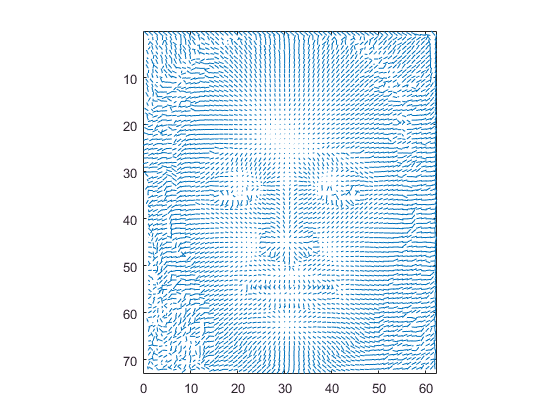

x = N(:,:,1);
y = N(:,:,2);
n = 6;
figure; % create a new figure
quiver(x(1:n:end,1:n:end),y(1:n:end,1:n:end),'.');
axis image; % set unit aspect ratio between x and y axes
axis ij; % place origin in top-left corner (like an image)

(b)

One potential source is that we do not consider interreflections meaning radience from other surface patches.

Since each surface patch is illuminated not only by sources, especially for the pathces around nostrils where cheek and bridge of nose can illuminate

One possible solution is to use a global shading model where the total radiosity of a patch will also take the radiosity due to all the other patches into acccount.


$$B(\mathbf v) = E(\mathbf v) + B_{incoming}(\mathbf v)  $$


(c)

We recover the image if the source $\hat\mathbf s = (0.58, −0.58, −0.58)$ or $\hat\mathbf s = (-0.58, −0.58, −0.58)$ with following formula and computed $ρ(\mathbf x)N(\mathbf x)$ from previous part


$$B(\mathbf x) = ρ(\mathbf x)N(\mathbf x)\cdot S_1$$


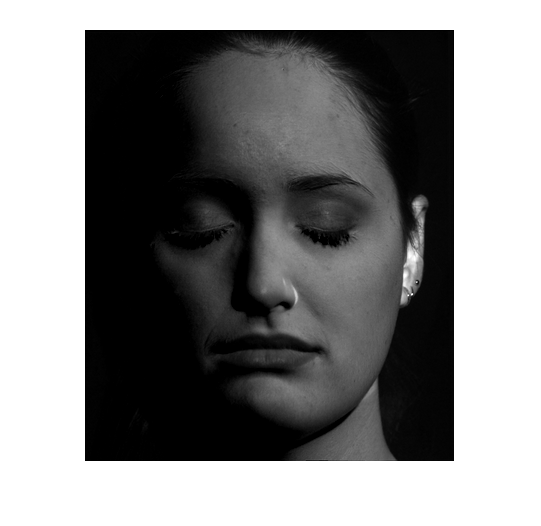

s1 =[0.58,-0.58,-0.58]; 
s2 =[-0.58,-0.58,-0.58]; 
I1 = zeros([p,q,1]);
I2 = zeros([p,q,1]);
for i=1:p
    for j=1:q
        I1(i,j,:) = max([0,squeeze(g(i,j,:))'*s1']);
        I2(i,j,:) = max([0,squeeze(g(i,j,:))'*s2']);
    end
end
figure
imshow(I1)

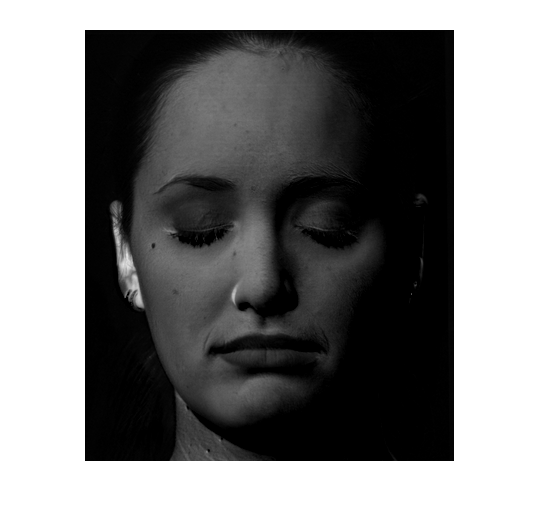

figure
imshow(I2)

(d)

We recover a surface *z*(*x, y*) from surface normals computed previously. The result is shown from two views.

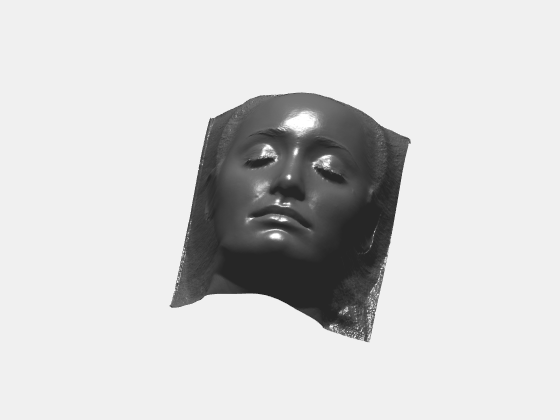

Z = integrate_frankot(N);
% Z is an HxW array of surface depths
figure;
s=surf(-Z); % use the ‘-’ sign since our Z-axis points down
% output s is a ‘handle’ for the surface plot
% adjust axis
axis image; axis off;
zlim([-200 200])
% change surface properties using SET
set(s,'facecolor',[.5 .5 .5],'edgecolor','none');
% add a light to the axis for visual effect
l=camlight;
% enable mouse-guided rotation
view([-170 60])
rotate3d on

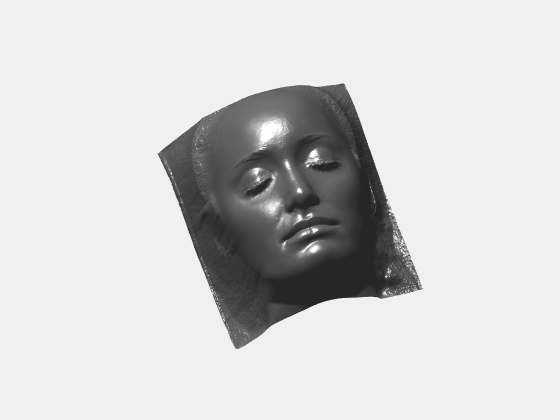

figure;
s=surf(-Z); % use the ‘-’ sign since our Z-axis points down
% output s is a ‘handle’ for the surface plot
% adjust axis
axis image; axis off;
zlim([-200 200])
% change surface properties using SET
set(s,'facecolor',[.5 .5 .5],'edgecolor','none');
% add a light to the axis for visual effect
l=camlight;
% enable mouse-guided rotation
view([-200 70])
rotate3d on

# Local Functions

You can put all possible functions here. 

function Z=integrate_frankot(N)
    %INTEGRATE_FRANKOT  Integrate surface from rectangular window of normals
    %  Z=INTEGRATE_FRANKOT(N) takes an PxQx3 field of normal vectors (the third
    %  dimension is [x y z]) and returns a PxQ array corresponding to the
    %  depth of the surface, with the mean depth equal to zero.
    %  
    %  Reference: Frankot, R. and Chellapa, R. (1988) "A Method for Enforcing
    %  Integrability in Shape from Shading Algorithms."  IEEE Trans. Pattern
    %  Anal. Mach. Intell. 10(4):439-451.
    
    %  Todd Zickler, November 2001; updated for CS283 Sept. 2004.
    
    [h,w]=size(N(:,:,1));
    
    % complain if P or Q are too big
    if (h>512) | (w>512)
      error('Input array too big.  Choose a smaller window.');
    end
    
    % pad the input array to 512x512
    nrows=2^9; ncols=2^9;
    
    % get surface slopes from normals; ignore points where normal is [0 0 0]
    x_sample=1;
    y_sample=1;
    zx=-x_sample*(sum(N,3)~=0).*N(:,:,1)./(N(:,:,3)+(N(:,:,3)==0));
    zy=-y_sample*(sum(N,3)~=0).*N(:,:,2)./(N(:,:,3)+(N(:,:,3)==0));   
       
    % compute Fourier coefficients
    if isempty(nrows)
       Zx=fft2(zx);
       Zy=fft2(zy);
       h2=h;w2=w;
    else
       Zx=fft2(zx,nrows,ncols);
       Zy=fft2(zy,nrows,ncols);
       h2=nrows; w2=ncols;
    end
    Zx=Zx(:); Zy=Zy(:);
    
    % compute repeated frequency vectors (See Chellapa paper)
    Wy=repmat(2*pi/h2*[0:(h2/2), (-(h2/2)+1):(-1)]',w2,1);
    Wx=kron(2*pi/w2*[0:(w2/2), (-(w2/2)+1):(-1)]',ones(h2,1));
    
    % compute transform of least squares closest integrable surface
    %    remove first column because it's all zeros (then add C(0)=0)
    C=(-j*Wx(2:end).*Zx(2:end)-j*Wy(2:end).*Zy(2:end))./...
      (Wx(2:end).^2+Wy(2:end).^2);
    
    % set DC component of C
    C=[0;C];
    
    % invert transform to get depth of integrable surface
    Z=real(ifft2(reshape(C,h2,w2)));
    
    % crop output if there was padding         
    if ~isempty(nrows)
       Z=Z(1:h,1:w);
    end   
end

function out=im2gray(im)
if size(im,3)>1
	out=im2double(rgb2gray(im));
else
	out=im2double(im);
end
end